# 1. Reconstruct angiogram data.

Dock figure(1) and use [this layout](https://docs.google.com/document/d/1RuEO2t5K-t82QPUK-sShLjorJyRC5uLGxchojfOiYDs/edit#heading=h.3m49wo5vra7y). 

## 10. Initiate.

Select a dataset to reconstruct. You can ignore a warning message (orange color) here. The values in the instruction below are default values. 

- pid : Process ID (processed data will be saved by this file name)

- IX = 1, IY = 1, IZ = 1 : Mosaic numbers in Y and Z (not used yet)

comInit;

pid = '10x-ang-jlee';  % Process ID

uid = 'jang';  % User ID
eid = '210621' ;  % Experiment ID
did = '10x_ang4';  % Data ID
IX = 1;  IY = 1;  IZ = 1;

pathraw = ['R:/ENG_Lee-Lab_Shared/group/data/16ThorlabsSD/' uid '/' eid];  % path of rawdata
pathdata = ['D:/' uid '/' eid];  % path to save reconstructed data
pathTemp = ['D:\temp\' uid '\' eid '\'];

if isempty(dir(pathdata))
    mkdir(pathdata);
end
if ~isempty(dir([pathdata '/' pid '.mat']))
    a1 = 'Oops, I will change pid.';
    a2 = 'Yes, I want to load it and may re-process and overwrite it.';
    a = questdlg('The Process ID already exist. Do you want to load it?','',a1,a2,a1);
    switch a
        case a1
            error('Please change pid and re-run this session.');
        case a2
            load([pathdata '/' pid '.mat']);
            disp('The existing processed data has been loaded.');
            pp
    end
else
    conf = ReadConf_16ThorlabsSD([pathraw '/' did '_.xml'])    
end

conf = struct with fields:
             dx: 1.5000
             dy: 1.5000
             x0: 0
             y0: 0
          Xstep: 1.5360
          Ystep: 1.5360
          Zstep: 0.2000
         intpDk: 0.2500
         X__mm_: 1.5360
     Bscan__ms_: 13.2681
         Y__mm_: 1.5360
     Volume__s_: 20.3260
    Memory__GB_: 64
     Time__min_: 1.3551
      Data__GB_: 64
        flyback: 0.0030
             nx: 1024
             ny: 1024
            apx: 1
            bpy: 2
             nv: 4
             MX: 1
             MY: 1
             MZ: 1


## 11. Copy raw data to the temporary folder. [15 min]

sec11;

SECTION 11 RUNNING ...
14:26  copying raw data to a temp folder ...
D:\temp\jang\210621\
14:38  copied.
SECTION 11 COMPLETED.


### 11a. Reconstruct the first volume as preview. [30 min]

SECTION 11 RUNNING ...
14:47 loaded 200/1024
14:53 loaded 400/1024
14:58 loaded 600/1024
15:03 loaded 800/1024
15:08 loaded 1000/1024
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).
15:14 motion correction... 800/1024
15:12 motion correction... 600/1024
15:11 motion correction... 200/1024
15:15 motion correction... 1000/1024
15:12 motion correction... 400/1024


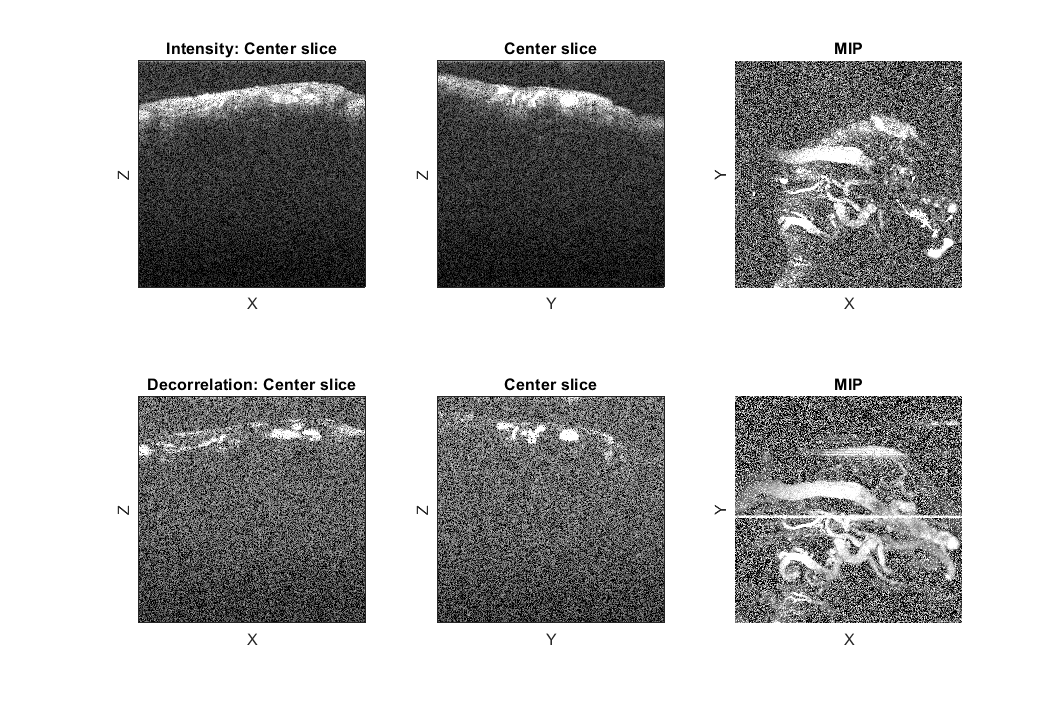

SECTION 11 COMPLETED.


sec11a;

## 12. Exclude glass images and other artifacts.

Please move up/down and rotate a plane, over which the images will be considered as artifacts and removed.

Parameters:

- dzc = 5 : Pixel numbers to move by E/D keys

- da = 0.01 : Angle (slope) to rotate by S/F/W/R keys

- ned = 100 : Pixel position from the edge to monitor the red plane

UI keys:

- Q: Quit

- G: Click four points: two points under the bottom glass artifact in X-Z plane and the same in Y-Z plane.

- E/D: Move the center of the plane 

- S/F: Rotate the plane along Y axis (in X-Z plane)

- W/R: Rotate the plane along X axis (in Y-Z plane)

SECTION 12 RUNNING ...


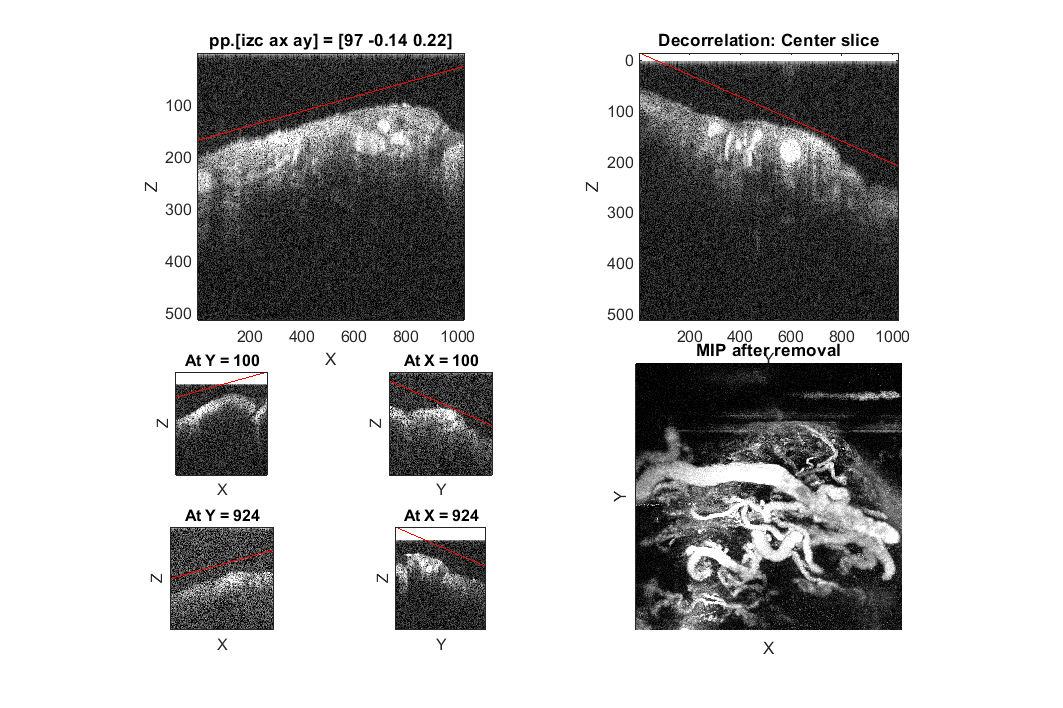

SECTION 12 COMPLETED.


dzc = 5;
da = 0.01;
ned = 100;

sec12;

**Check points:**

- Do your red plane position well in the four small figures as well?

- Did large-area artifacts disappear from the MIP?

## 13. Determine the optimal *dk* value.

If you want to find the optimal value for this dataset, set *dk* = 0 and run section. If you already know what is optimal and want to use it, set the non-zero value below and run this section.

- pp.dk = 0 : If you already know the optimal value and want to skip this section, set the value and run this section.

- dkr = 0.23+(-4:4)*0.01 : The range of dk to test. If this section cannot find the optimal, try different ranges.

- iydk = ny*1/2 : The B-scan index to test. You could use ny*1/4 or ny*3/4.

SECTION 13 RUNNING ...
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


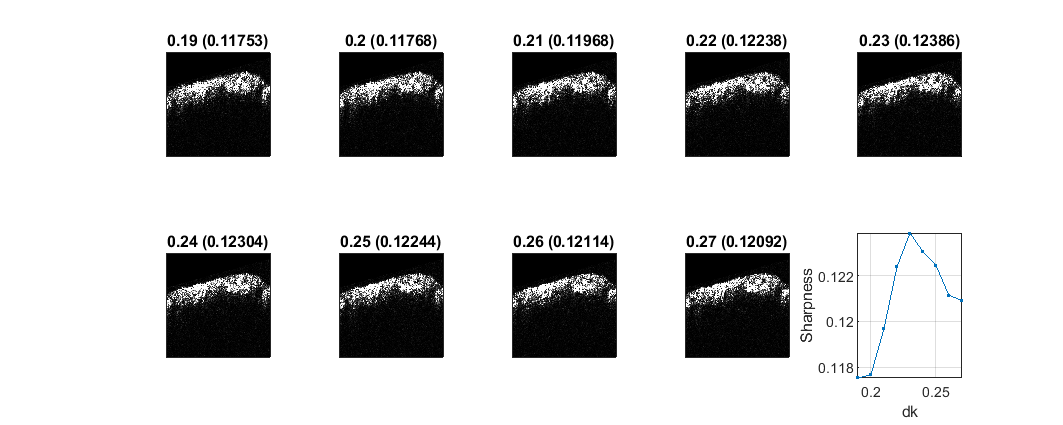

pp = struct with fields:
    izc: 97
     ax: -0.1387
     ay: 0.2179
     dk: 0.2300


SECTION 13 COMPLETED.


pp.dk = 0;  % find a new value only when this is set to zero.
dkr = 0.23+(-4:4)*0.01;
iydk = ny*1/2;

if pp.dk == 0
    sec13;
end

**Check points:**

- Is your sharpness curve concave with a clear maximum?

## 14. Determine the bottom depth to crop.

Parameters

- DR = 10 : Dynamic range for the initial guess (nz1 s.t. Dz(nz1) = max(Dz)/DR)

- dz = 20 : Pixel number to move the depth

UI keys

- Q: Quit

- G: Select the bottom depth manually.

- S/F: Move the bottom depth 

SECTION 14 RUNNING ...


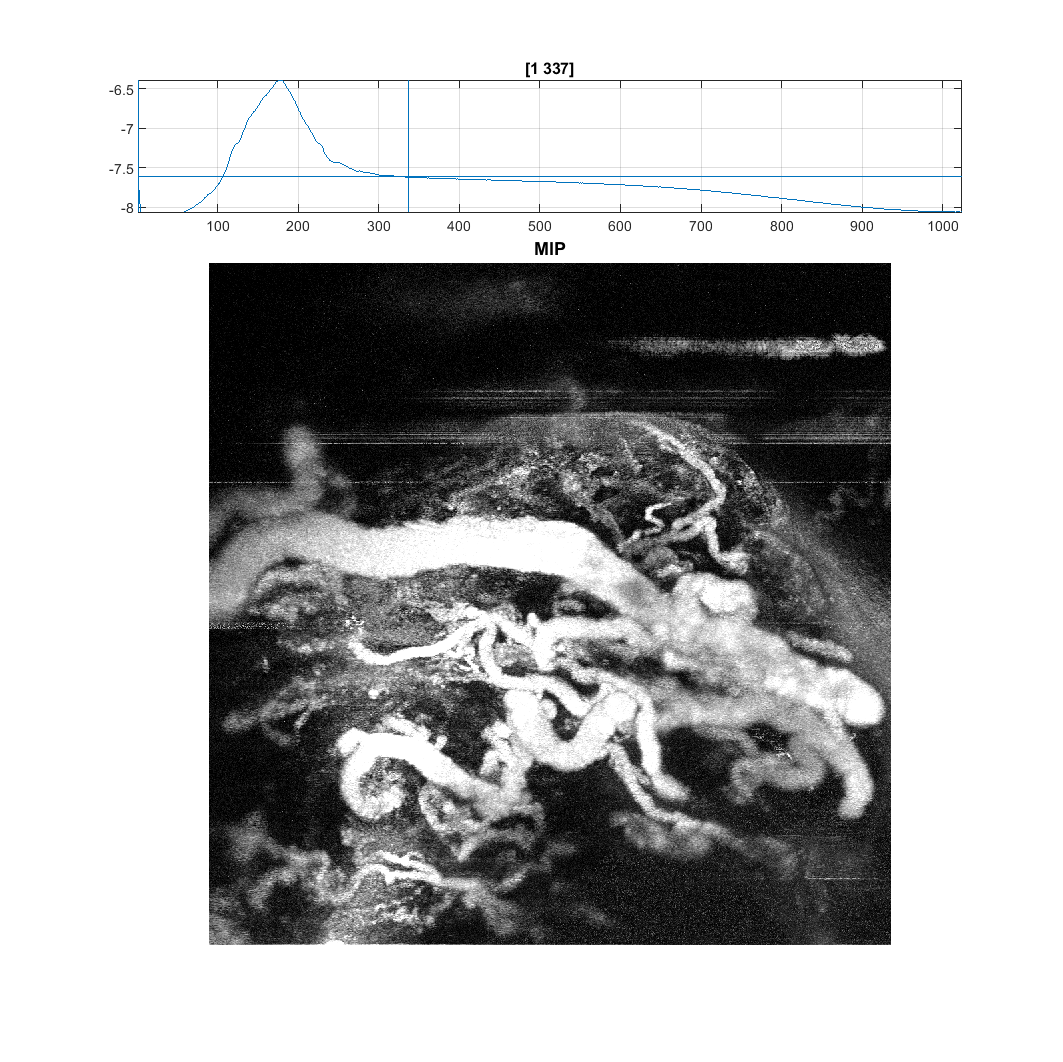

SECTION 14 COMPLETED.


DR = 10;
dz = 20;

sec14;

## 15. Reconstruct all volumes and conduct the automatic contrast-masked averaging. [2-3 hr]

Parameters

- pp.nvexc = 1 : Number of volume data to exclude from averaging for each Y position.  

- pp.medfsize = [3 3 3] : Kernel size of median filtering before averaging, No when [0 0 0]

- pp.gaussize = [5 5 5] : Kernel size for Gaussian filtering after volume average. No when [0 0 0]. The default [5 5 5] means 1/e at px=1

- bFig = false: Plot the contrast(y) over volumes?

SECTION 15 RUNNING ...
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


16:41 reconstructing... 1/4 500/1024
16:52 reconstructing... 1/4 1000/1024
16:54 motion correction... 1/4 500/1024
16:57 motion correction... 1/4 1000/1024


17:13 reconstructing... 2/4 500/1024
17:28 reconstructing... 2/4 1000/1024
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).
17:30 motion correction... 2/4 500/1024
17:31 motion correction... 2/4 1000/1024


17:47 reconstructing... 3/4 500/1024
18:03 reconstructing... 3/4 1000/1024
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).
18:05 motion correction... 3/4 500/1024
18:06 motion correction... 3/4 1000/1024


18:21 reconstructing... 4/4 500/1024
18:36 reconstructing... 4/4 1000/1024
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).
18:38 motion correction... 4/4 500/1024
18:39 motion correction... 4/4 1000/1024


18:40  Median filtering ... 1/4
18:40  Median filtering ... 2/4
18:40  Median filtering ... 3/4
18:40  Median filtering ... 4/4


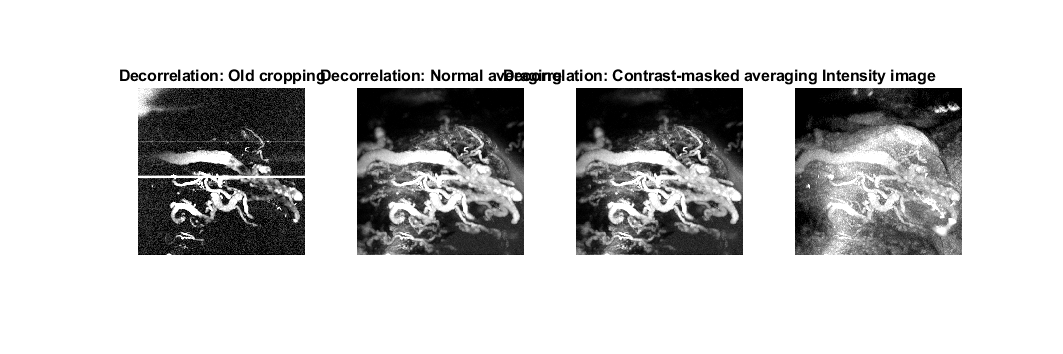

SECTION 15 COMPLETED.


pp.nvexc = 1;
pp.medfsize = [3 3 3];
pp.gaufsize = [5 5 5];
bFig = true;

sec15;

## 19. Save reconstructed data and delete the raw files from the temporary folder. [<1 GB]

if ~isempty(dir([pathdata '/' pid '.mat']))
    disp(['Overwriting Data ...']);
else 
    disp('Saving Data ...');
end

Saving Data ...


clear I D frg;
save('-v7.3',[pathdata '/' pid '.mat']);
disp('Data Saved.');

Data Saved.


delete([pathTemp did '*.*']);
if numel(dir(pathTemp)) < 3
    rmdir(pathTemp);
end
disp('Temp data deleted.')

Temp data deleted.


disp(['Recommended report file name:' newline '1 Reconstruct - ' uid ' - ' eid ' - ' pid '.pdf']);

Recommended report file name:
1 Reconstruct - jang - 210621 - 10x-ang4.pdf


You may also want to export this live script to a report in PDF. Run *Live Editor > Save > Export to PDF*.

**Please do *****not *****save report files under GitHub folders**. Recommened are:

- Space: *\\files.brown.edu\research\ENG_Lee-Lab_Shared\group\report\ad-16-ko-mouse\Angiogram*

- You can copy the path of space and paste it into the export window.

- File name: printed above